clear; close all; clc; % initializes environment

# 主成分分析（Principle Component Analysis: PCA）の概説

## 本章の目的

### 次元削減

主成分分析（Principle Component Analysis; 以下，PCA）は，多変量データがもつ情報をなるべく損なわないようにしたうえで，できるだけ少ない変数（たとえば２～３変数）でデータを表す際に用いられる手法です．このような手法は次元削減または次元圧縮と呼ばれます．次元削減によってデータの主要な特徴を効率よく把握することが期待できるため，未知の多変量データを手にした際には，初期段階での強力な解析ツールになります．また，重回帰分析などのほかの多変量解析を行う際も，次元削減されたデータを用いることで，重回帰分析のパフォーマンスが向上したり，回帰モデルの意味を把握しやすくなったりすることが期待できます．このような意味において，次元削減は多変量解析の土台となるような手法と言えます．

### 主成分分析

次元削減のなかでも主成分分析は，数学的な背景が比較的シンプルであり，理解しやすい手法です．主成分分析で次元削減する際に保存される情報は「分散」です．言い換えると，主成分分析はデータがもつ分散をできる限り保存するようにして，変数の数を減らす手法です．PCAによる次元圧縮は以下の３つのステップとして捉えることができます．

- データの分散をもっともよく説明する方向（主軸）をみつける

- 主軸が座標軸となるようにデータを回転させる

- 主軸（新たな座標軸）のうち，分散が大きな軸を残して，残りを捨てる（無視する）

本章では，このようなステップを実際のデータを用いてできるだけ視覚的に解説していきます．まず本章で用いるデータを準備し，つぎにPCAの実行手順を実際のデータを使って概説します．データの解析にはMATLAB Statistcis and Machine Learning Toolboxに付属のpca()という関数を利用します．つづいて，pca()関数の３つの出力結果（「主成分係数」「主成分スコア」「主成分分散」）の意味をできるだけ視覚的に解説します．最後にPCAによる次元削減を上記の３つのステップに対応させて解説します．

## データの準備

本章でも前章に引き続き，「米国３２９都市の生活満足度」データセットを用います．

load cities.mat; % loads dataset

解説を簡単にするために，ratingsから二変数（「健康」および「芸術」）を取り出し，二変量データとして扱います．

scores_health = ratings(:, 3); % extracts scores on healt (the 3rd  column)
scores_arts = ratings(:, 7); % extracts scores on arts (the 7th column)

通常，このような場合にはPCAを行う必要はありませんが，PCAをできるだけ視覚的に解説するためです．

### データの確認

確認のために散布図を作成します（図２－１）．

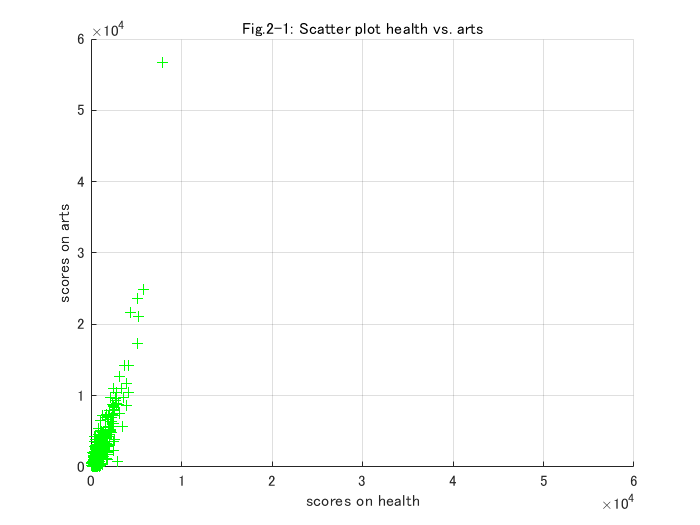

figure('Name','Fig.2-1. Scatter plot: health vs. arts'); % creats a new figure window
scatter(scores_health, scores_arts, 'g+'); grid on; % plots a scatter plot on the figure window
title('Fig.2-1: Scatter plot health vs. arts'); % adds title
xlabel('scores on health'); ylabel('scores on arts'); % add labes
axis([0 60000 0 60000]);

横軸が「教育」に関する評価値で，縦軸が「芸術」に関する評価値です．「教育」の評価値の範囲は０から１００００ですが，「芸術」の評価値は最大値が６００００近くに及んでいます．「教育」と「芸術」の評価値の最大値が大きく異なっており，散布図が左に大きく偏っています．

### 正規化

散布図を見やすくするために，平均値が０，標準偏差が１になるようにそれぞれの変数を変換します．このような操作を正規化といいます．正規化にはnormalize()という関数を使います．

scores_health_norm = normalize(scores_health); % normalizes scores on health
scores_arts_norm = normalize(scores_arts); % normalizez scores on arts

念のために，正規化されているかを確認します．まずはそれぞれの平均値を計算します．いずれも限りなく０になっていることを確認してください．

mean(scores_health_norm) % computes average of scores on health

ans = -3.8807e-17

mean(scores_health_norm) % computes average of scores arts

ans = -3.8807e-17

つぎに，標準偏差についても計算します．こちらは，それぞれ１になっていることを確認してください．

std(scores_health_norm)

ans = 1

std(scores_arts_norm)

ans = 1.0000

### 正規化データの散布図

正規化されたデータの散布図を確認します（図２－２）．

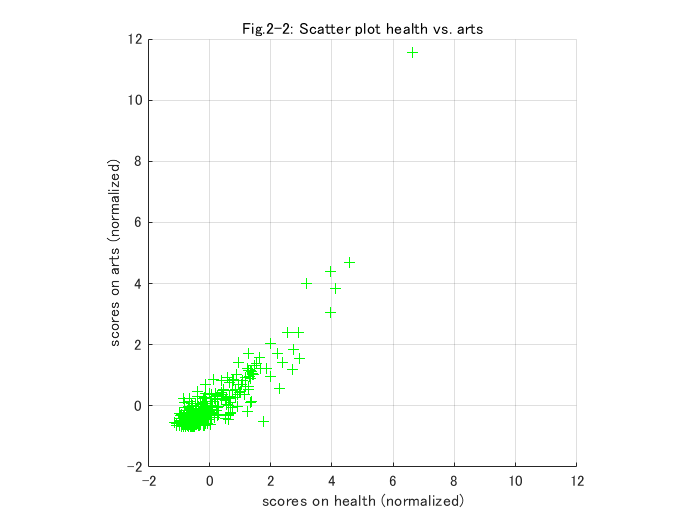

figure('Name','Fig.2-2. Scatter plot: health vs. arts'); % creats a new figure window
scatter(scores_health_norm, scores_arts_norm, 'g+'); grid on; % plots a scatter plot on the figure window
title('Fig.2-2: Scatter plot health vs. arts'); % adds title
xlabel('scores on health (normalized)'); ylabel('scores on arts (normalized)'); % add labes
axis([-2 12 -2 12]); axis square;

先程と同様，横軸が「教育」の得点，縦軸が「芸術」の得点を表しています．先ほどの図２－１と比較すると，正規化の結果，データの分布の中心が原点$O\left(0,0\right)$になり，各軸のスケールが小さくなっています．

### 正規化に関する注意

データの正規化はPCAの前処理として行われる場合があります．一般的には，異なる単位の変数（身長や体重など）からなるデータだったり，分布範囲が大きく異なる変数が含まれるデータだったりする場合に変数ごとに正規化を行うことが多いようです．極端に大きな値を含む変数がある場合，その変数がPCAの結果に大きな影響を与えてしまう可能性があります．そのような影響を抑えるためです．しかし，正規化は元のデータを変えてしまうことになり，PCAの結果も変わってしまうことになります．実施するかどうかや，正規化データを用いたPCAの結果の解釈には慎重な判断が必要です．ここでは，説明を簡単にするために正規化したデータを使って説明を続けていきます．

## PCAの手順

次に，pca()関数を用いたPCAの手順について簡単に解説していきます．といっても，PCAを行う手順自体に複雑なことはありません．現在，PCAはコンピュータ上で比較的簡単に実行できるようになっています．「MATLAB（ただし，Statistics and Machine Learning Toolbxoが必要）」や，統計分析フリーソフトウェア「R」，汎用フリープログラミング言語「Python」などが使える環境であれば，関数にデータを放り込むだけでPCAの結果を得ることが出来ます．関数とは，ある値を与えると別の値を返すプログラムといえます．したがって，あるプログラミング言語でPCAを実行する場合（その言語にPCAの関数が用意されていれば），その手順は，

- 関数にデータを与える

- 関数の処理結果を受け取る

というとてもシンプルなものです．たとえば，「MATLAB」の「Statistics and Machine Learning Toolbox」にはpca()という関数が準備されています．前セクションで準備したデータを用いてPCAを行う場合には，コマンドウィンドウで以下のように実施します．

[coefs, scores, latents] = pca([scores_health_norm scores_arts_norm],'Algorithm','eig');

これでPCAの主要な結果が得られます．イコール記号（＝）の右側で，pca()関数を実行しています．イコール記号の右側は，実行結果を３つの変数（coefs, scores, latents）に代入しています．上記の例では，pca()の括弧の中で，解析の対象となるデータ（[scores_health_norm scores_arts_norm]）を指定しています．データに続いて，'Algorighm'と'eig'のセットで，PCAのアルゴリズム（計算方法）を指定しています．pca()関数では３つのアルゴリズム（「特異値分解」「固有値分解」「交互最小二乗」）を指定できるようになっています．ここでは'eig'として，「固有値分解」を指定しています．固有値分解の意味については，次章以降で詳しく説明していきます．なお，MATLABをでは関数の括弧の中に渡す値（数値や文字列）を「入力引数」と呼んでいます．イコール記号は代入を表す記号です．pca()の計算結果をイコールの左側にある変数に代入します．ここでは，coef, scores, latentの３つの変数がそれぞれ異なる結果を受け取ります．MATLABAではこれらの変数を「出力引数」と呼びます．本稿では簡単な例を使って，これら３つの出力引数を説明していきます．

### ヘルプ，ドキュメンテーション

MATLABのpca()関数には，上記以外にも入力引数や出力引数を指定することが出来ます．pca()関数がどのような入力引数や出力引数をとるかは，ヘルプで調べることができます．ヘルプを参照するためにはコマンドウィンドウで以下のように実行してください．

help pca

pca - 生データの主成分分析

    この MATLAB 関数 は、n 行 p 列のデータ行列 X の主成分係数 (負荷量とも呼ばれます) を返します。

    coeff = pca(X)
    coeff = pca(X,Name,Value)
    [coeff,score,latent] = pca(___)
    [coeff,score,latent,tsquared] = pca(___)
    [coeff,score,latent,tsquared,explained,mu] = pca(___)

    参考 <a href="https://localhost:31515/static/help/stats/barttest.html">barttest</a>, <a href="https://localhost:31515/static/help/stats/biplot.html">biplot</a>, <a href="https://localhost:31515/static/help/stats/canoncorr.html">canoncorr</a>, <a href="https://localhost:31515/static/help/stats/factoran.html">factoran</a>, <a href="https://localhost:31515/static/help/stats/pcacov.html">pcacov</a>, <a href="https://localhost:31515/static/help/stats/pcares.html">pcares</a>, <a href="https://localhost:31515/static/help/stats/ppca.html">ppca</a>, 
        <a href="https://localhost:31515/static/help/stats/rotatefactors.html">rotatefactors</a>

    pca のリファレンス ページ
    

また，入力引数や出力引数の説明やpca()関数の詳しい使い方に関してはドキュメンテーションを参考にすることが出来ます．ドキュメンテーションを見るためには，コマンドウィンドウで以下のようにします（%を外して実行すると別ウィンドウが開きます）．

%doc pca

さらに，pca()関数には，より実践的な解説ページがあります．下記のURLからアクセスしてみてください．

[https://jp.mathworks.com/help/stats/quality-of-life-in-u-s-cities.html](https://jp.mathworks.com/help/stats/quality-of-life-in-u-s-cities.html)

## PCAの出力引数

前述の例では，coefs, scores, latentsという変数名でpca()関数の３つの出力引数を受け取っています．これらの変数名は任意の文字列で指定することができます．MATLABでは，これらの出力引数は「主成分係数」「主成分スコア」「主成分分散」という一般名称で呼ばれています．これらの３つの出力引数について，具体例を使って解説していきます．

### 主成分係数行列

まずは，１つ目の出力引数について解説します．この出力引数は一般的に主成分係数と呼ばれています．上記の例ではcoefsという変数です．coefsの内容を表示させると，

coefs

coefs =     0.7071   -0.7071
    0.7071    0.7071


coefsは２行２列の行列になっています．

#### 主成分係数の幾何学的な解釈

主成分係数coefsの各列は，データの分布がもっとも広がる方向（一列目）とそれに直交する方向（二列目）を表しています．それを確認するために，データの散布図に，coefsの各列が示す向きを矢印として追加します（図２－３）．

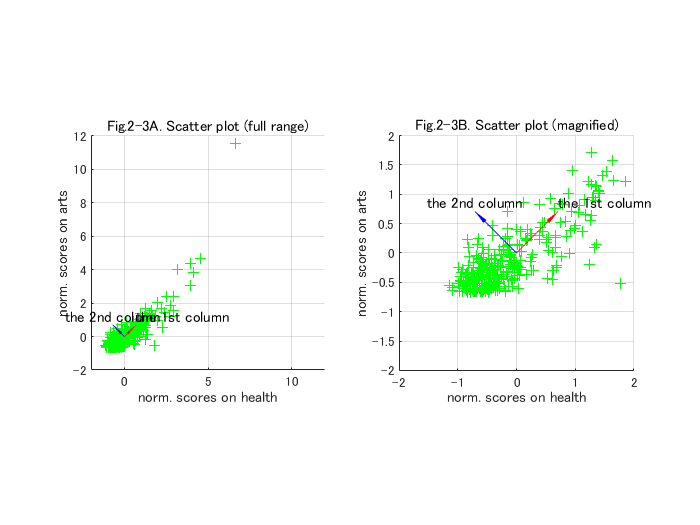

figure('Name','Fig.2-3. Scatter plots with pca coefs');
subplot(1,2,1);
scatter(scores_health_norm,scores_arts_norm,'g+'); hold on; grid on;
title('Fig.2-3A. Scatter plot (full range)');
xlabel('norm. scores on health'); ylabel('norm. scores on arts');
daspect([1 1 1]);
arrow3([0 0], coefs(:,1)','r-'); text(coefs(1,1),coefs(2,1),'the 1st column','VerticalAlignment','bottom');
arrow3([0 0], coefs(:,2)','b-'); text(coefs(1,2),coefs(2,2),'the 2nd column','VerticalAlignment','bottom','HorizontalAlignment','center');
axis([-2 12 -2 12]); axis square;
subplot(1,2,2);
scatter(scores_health_norm,scores_arts_norm,'g+'); hold on; grid on;
title('Fig.2-3B. Scatter plot (magnified)');
xlabel('norm. scores on health'); ylabel('norm. scores on arts');
daspect([1 1 1]);
arrow3([0 0], coefs(:,1)','r-',0.3,1); text(coefs(1,1),coefs(2,1),'the 1st column','VerticalAlignment','bottom');
arrow3([0 0], coefs(:,2)','b-',0.3,1); text(coefs(1,2),coefs(2,2),'the 2nd column','VerticalAlignment','bottom','HorizontalAlignment','center');
axis([-2 2 -2 2]); axis square;

左図（図２－３A）は先ほどと同じ図（図２－２）に矢印を追加したものです．右図（図２－３B）は矢印が見えやすくなるように，原点の周りを拡大して表示しています．いずれの場合も，赤色の矢印はcoefsの第一列目を成分とするベクトルを表し，青色の矢印は第二列目を成分とするベクトルを表します．水色の点は図２－２と同様のデータを表します．データの分布と赤色矢印の方向を見比べると，赤色の矢印（coefsの第一列目）が示す方向とデータの分布が最も広がっている方向が一致しているように見えます．また，青色の矢印（coefsの第二列目）は，赤色矢印と直角に交わっ（直交し）ているように見えます．

#### 主軸

主成分係数の各列が示す方向は「主軸」と呼ばれます．主軸の数（＝主成分係数の列数）はデータの変数の数と一致します．それぞれの主軸はデータの広がり（＝分散）ができるだけ大きくなるような方向またはそれに直交する方向を示します．これらの方向は，データの分散をもっともよく説明する方向です．詳しくは「主成分スコア」および「主成分分散」の項で解説します．

### 主成分スコア

つぎに，２つ目の引数を説明します．前述の例ではscoresという変数がそれに当たります．MATLABドキュメンテーションでは「主成分スコア」と呼ばれています．scoresの内容を確認すると

scores

scores =    -0.9971    0.3406
    0.6991    0.0360
   -0.8441   -0.0436
    0.4020    0.0562
    0.6753   -0.2655
   -0.8138   -0.0443
   -0.5227    0.2736
   -0.4091   -0.0978
   -0.9723    0.0904
   -0.6561    0.0725


３２９行２列の行列であることがわかります．行数はデータの観測の数と一致します．また，列の数はデータの変数の数と一致します．

#### 主成分スコアの幾何学的な解釈

主成分スコアscoresの１列目を横軸に，二列目を縦軸にした散布図は，さきほどの主軸（＝主成分係数の各列）が座標軸（横軸および縦軸）になるようにデータを回転させてものと一致します．実際に散布図を作って確認してみます．

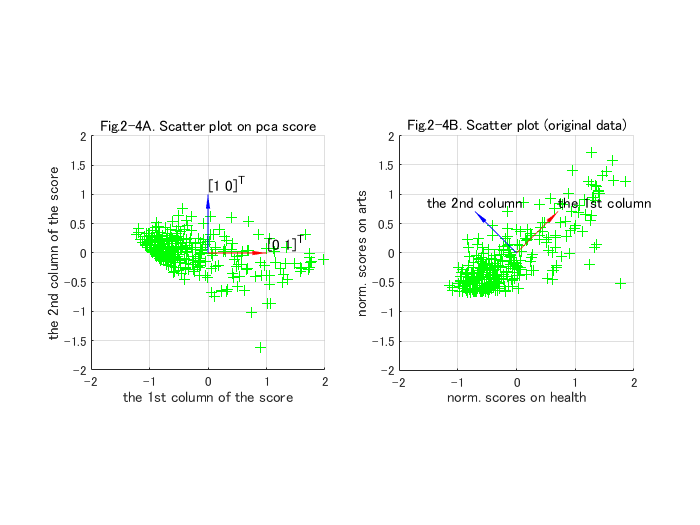

figure('Name','Fig.2-4. Scatter plots on pca score');
subplot(1,2,1);
scatter(scores(:,1),scores(:,2),'g+'); hold on; grid on;
title('Fig.2-4A. Scatter plot on pca score');
xlabel('the 1st column of the score'); ylabel('the 2nd column of the score');
daspect([1 1 1]);
arrow3([0 0], [1 0],'r-',0.3,1); text(0, 1,'[1 0]^{T}','VerticalAlignment','bottom');
arrow3([0 0], [0 1],'b-',0.3,1); text(1,0,'[0 1]^{T}','VerticalAlignment','bottom');
axis([-2 2 -2 2]); axis square;
subplot(1,2,2);
scatter(scores_health_norm,scores_arts_norm,'g+'); hold on; grid on;
title('Fig.2-4B. Scatter plot (original data)');
xlabel('norm. scores on health'); ylabel('norm. scores on arts');
daspect([1 1 1]);
arrow3([0 0], coefs(:,1)','r-',0.3,1); text(coefs(1,1),coefs(2,1),'the 1st column','VerticalAlignment','bottom');
arrow3([0 0], coefs(:,2)','b-',0.3,1); text(coefs(1,2),coefs(2,2),'the 2nd column','VerticalAlignment','bottom','HorizontalAlignment','center');
axis([-2 2 -2 2]); axis square;

左図（図２－４A）は主成分スコアscoresの一列目を横軸，二列目を縦軸にとった散布図です．赤矢印と青矢印はそれぞれ横軸と縦軸の方向を表す単位ベクトルです．右図（図２－４B）は，もとのデータの散布図です．赤矢印と青矢印はそれぞれ，１つ目の主軸（主成分係数coefsの一列目）と２つ目の主軸（主成分係数coefsの二列目）のベクトルが表す方向です．いずれも矢印を見やすくするために原点付近を拡大して表示しています．２つの図を見比べると，主成分スコアの散布図は，もとのデータが横軸方向に回転したもののように見えます．

#### 主成分スコアの意味

主成分スコアは主軸（主成分係数の各列が示す方向）が座標軸になるようにもとのデータを回転させたときの座標を表します．言い換えると，主成分スコアの各行は，主成分係数を新しい座標軸にしたときの座標です．

### 主成分分散

最後に，３つめの出力引数について説明します．この出力引数の一般名称は「主成分分散」です．前述の例では，latentsという変数がそれに当たります．latentsの内容を表示させます．

latents

latents =     1.8658
    0.1342


latentsは２行１列の列ベクトルです．それぞれの値は，主成分スコアscoresの各列の分散を表します．実際に，主成分スコアscoresの列ごとの分散を計算してみます．

var(scores)

ans =     1.8658    0.1342


このようにlatentsの各要素の値と，主成分スコアscoresの列ごとの分散は一致します．

#### 主成分分散の幾何学的解釈

主成分分散latentsの２つの要素は，主成分スコアscoresの列ごとの分散であることを指摘しました．幾何学的に解釈すると，図２－４Aの横軸方向と縦軸方向の分散を表します．データの平均は０になるように正規化していますので，原点から各データ点までの距離の二乗が分散になります．また，図２－４AとBは座標を回転させた関係にあり，それぞれの赤矢印と青矢印はデータの分布に置いておなじ方向を示します．したがって，主成分分散latentsの各要素は，図２－４Bの１つ目の主軸（赤矢印の方向）と２つ目の主軸（青矢印の方向）における分散とも一致します．

#### 二変量データの全分散

ここで二変量データの分散について述べておきます．分散は平均値からのズレを指標化したものです．二変量データは二次元空間に広がりますから，その全分散を評価するためには，直交する２つの方向でそれぞれ分散を求める必要があります．図２－４Bの場合を例にすると，主成分分散latentsの各要素は，２つの主軸方向における分散を表します．主軸は互いに直交しますので，latentsの要素の総和がこのデータがもつ全分散になります．すなわち，今回のデータの全分散は

sum(latents)

ans = 2.0000

となります．

#### 二変量データの分散と軸の方向

前述したように，二変量データ（あるいは多変量データ）の分散を計算する際には，直交する二つの軸（方向）でそれぞれ分散を求める必要があります．その際，どの方向を軸にするかによって分散の値が変化します．図２－４Bを例にして具体的に見てみましょう．以下に図２－４Bを再掲します．

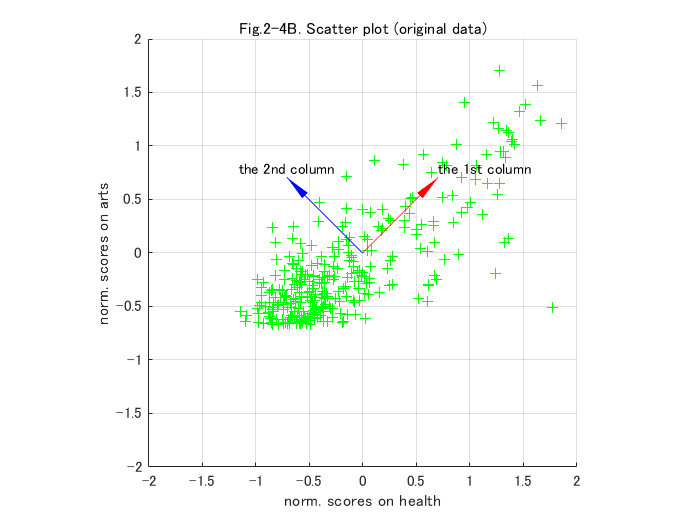

figure('Name','Fig.2-4B');
scatter(scores_health_norm,scores_arts_norm,'g+'); hold on; grid on;
title('Fig.2-4B. Scatter plot (original data)');
xlabel('norm. scores on health'); ylabel('norm. scores on arts');
daspect([1 1 1]);
arrow3([0 0], coefs(:,1)','r-',0.3,1); text(coefs(1,1),coefs(2,1),'the 1st column','VerticalAlignment','bottom');
arrow3([0 0], coefs(:,2)','b-',0.3,1); text(coefs(1,2),coefs(2,2),'the 2nd column','VerticalAlignment','bottom','HorizontalAlignment','center');
axis([-2 2 -2 2]); axis square;

さきほど，主成分分散latentsの各要素は，各主軸方向（図中赤矢印および青矢印）におけるデータの分散と解説しました．それぞれの値は以下のようになります．

latents

latents =     1.8658
    0.1342


次に，散布図の横軸と縦軸の方向でそれぞれ分散を求めてみます．「健康」と「芸術」の評価値，それぞれの分散を求めます．

var([scores_health_norm scores_arts_norm])

ans =     1.0000    1.0000


二つの結果を比較すると，主軸方向と座標軸方向で計算される分散が異なることがわかります．このように二変量データや多変量データで分散を求める場合は，どの軸の分散を求めるかによって結果が変わってきます．

#### 全分散の保存

前述したように，二変量データで分散を求める際には，直交する２つの方向で分散を求める必要があり，どの軸で分散を求めるかによって値が変化します．しかし，どの軸で分散を求めても，分散の総和は同じになります．たとえば，主軸方向の全分散をもとめてみると，

sum(latents)

ans = 2.0000

となります．主成分分散latentsはそれぞれの主軸方向での分散であり，その総和はデータの全分散です．この場合，２となります．次に，座標軸方向の分散を求めると，縦軸と横軸方向のデータの分散はそれぞれ，

var([scores_health_norm scores_arts_norm])

ans =     1.0000    1.0000


となります．その総和は主成分分散の和と一致します．

sum(var([scores_health_norm scores_arts_norm]))

ans = 2.0000

このように，全分散は軸のとり方によらず（それぞれの軸が互いに直交している必要はあります）保存されます．

#### 主成分分散の重要性

二変量データおよび多変量データにおいて分散を求める際には，どの方向の分散を求めるかによって値が変わることを解説しました．したがって，分散を求める向きが重要な問題になることがあります．PCAではまさにこの問題が重要となります．ここで再び，主成分係数の各列が示す方向における分散（主成分分散latents）と，座標の横軸と縦軸方向の分散を比較してみます．

主軸方向の分散（主成分分散：latents）：

latents

latents =     1.8658
    0.1342


座標軸方向の分散：

var([scores_health_norm scores_arts_norm])

ans =     1.0000    1.0000


前述したように全分散は保存されますが，それぞれの軸で表現される分散が異なります．座標軸方向の分散はそれぞれ（横軸と縦軸）の方向で，データの分散が半分ずつ含まれています．主成分分散の場合は，１つ目の主軸にデータの分散の大半が含まれるようになります．言い換えると，１つ目の主軸でデータの分散のほとんどが含まれるようになっています．

## PCAによる次元圧縮

次元圧縮または次元削減とは，多変量データに対して，データが本来持つ変数の数（次元）よりも少ない変数でデータを表現するために用いられる手法です．上記の二変量データの場合を例にすると，二次元のデータを一次元で表すことが次元圧縮になります．より少ない変数（次元）でデータを見ることができるため，データの概要を把握しやすくなります．その反面，一次元分の情報を失ってしまうことになります．次元圧縮の際には，データがもつ情報をできる限り保存するような方法で削減する次元（保存する次元）を決める必要があります．PCAでは次元削減の基準としてデータがもつ分散を利用し，以下のようなステップで次元圧縮を行います．

- データの分散をもっともよく説明する方向（主軸）をみつける

- 主軸が座標軸となるようにデータを回転させる

- 主軸（新たな座標軸）のうち，分散が大きな軸を残して，残りを捨てる（無視する）

このようなステップ，データがもつ分散を最大限に保存するように次元を選び，削減していきます．その際，上記の「主成分係数」「主成分スコア」「主成分分散」が重要な意味を持ちます．以下では，上記の各ステップと「主成分係数」「主成分スコア」「主成分分析」を対応させながら，PCAによる次元圧縮を解説します．できるだけ図形的なイメージで解説できるよう，解説には前述の二変量データを使います．

### １．データの分散をもっともよく説明する軸（「主成分係数）

データの分散をもっともよく説明する軸とは，前述の主軸のことであり，主成分係数coefsの各列が示す方向にあたります．以下に図２－３Bを再掲します．

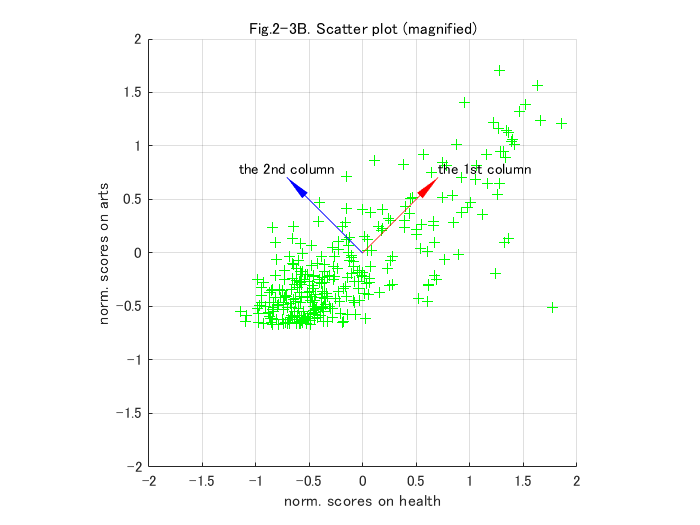

figure('Name','Fig.2-3B');
scatter(scores_health_norm,scores_arts_norm,'g+'); hold on; grid on;
title('Fig.2-3B. Scatter plot (magnified)');
xlabel('norm. scores on health'); ylabel('norm. scores on arts');
daspect([1 1 1]);
arrow3([0 0], coefs(:,1)','r-',0.3,1); text(coefs(1,1),coefs(2,1),'the 1st column','VerticalAlignment','bottom');
arrow3([0 0], coefs(:,2)','b-',0.3,1); text(coefs(1,2),coefs(2,2),'the 2nd column','VerticalAlignment','bottom','HorizontalAlignment','center');
axis([-2 2 -2 2]); axis square;

主軸の方向は矢印で示されており，赤矢印が１つ目の主軸（主成分係数coefsの一列目）の方向を表し，青矢印は２つ目の主軸（主成分係数coefsの二列目）の方向を表します．先ほど，確認したように，１つ目の主軸にはデータが持つ全分散のうち，ほとんどが集中します．その割合を計算すると，

latents/sum(latents)*100

ans =    93.2898
    6.7102


１つ目の主軸には，全分散の９割以上が含まれています．このように，全分散のうちもっとも多い割合を含む主軸のことを第一主成分と呼ぶことがあります．全分散のうち二番目に多い分散を含む主軸は第二主成分といいます．上記の例の場合だと，２つ目の主軸が第二主成分にあたります．

### ２．主軸が座標軸になるように回転させる

主軸が座標軸となるように回転させたときの座標が主成分スコアscoresになります．scoresの各行が，ひとつの点の座標にあたります．第一主成分を横軸，第二主成分を縦軸にしたときの散布図を再掲します．

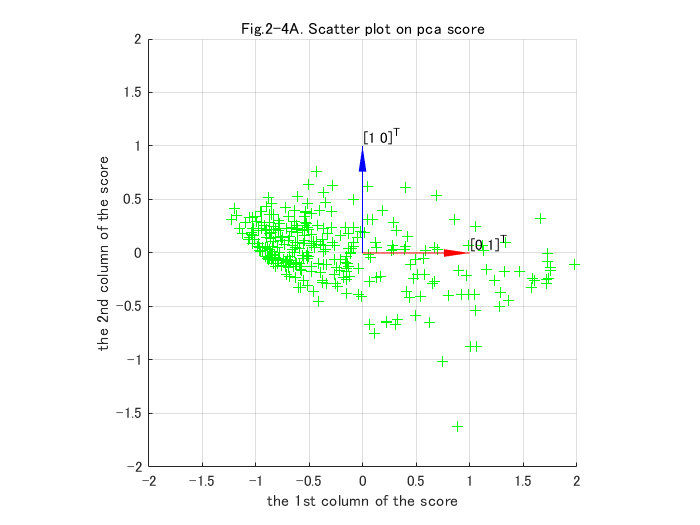

figure('Name','Fig.2-4A. Scatter plots on pca score');
scatter(scores(:,1),scores(:,2),'g+'); hold on; grid on;
title('Fig.2-4A. Scatter plot on pca score');
xlabel('the 1st column of the score'); ylabel('the 2nd column of the score');
daspect([1 1 1]);
arrow3([0 0], [1 0],'r-',0.3,1); text(0, 1,'[1 0]^{T}','VerticalAlignment','bottom');
arrow3([0 0], [0 1],'b-',0.3,1); text(1,0,'[0 1]^{T}','VerticalAlignment','bottom');
axis([-2 2 -2 2]); axis square;

このように回転すると，横軸方向にデータの分散が９割以上含まれるようになります．

### ３．主軸（新たな座標軸）のうち，分散が大きな軸を残して，残りを捨てる（無視する）

ステップ１，２で次元削減の準備が整いました．図２－４Aでは横軸方向にデータの分散が９割以上含まれています．したがって，データを横軸（第一主成分）方向のみの一次元で表しても，９割以上の情報は残ることになります．以下に，主成分スコアの第二列目（第二主成分に相当）を０にした散布図を示します．

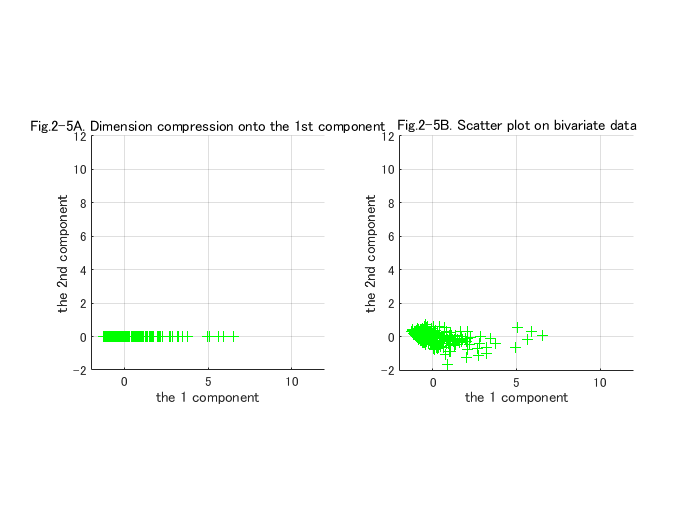

figure('Name','Fig.2-5. Dimension compression onto the 1st component');
subplot(1,2,1);
scatter(scores(:,1),zeros(size(scores(:,2))),'g+'); hold on; grid on;
title('Fig.2-5A. Dimension compression onto the 1st component');
xlabel('the 1 component'); ylabel('the 2nd component');
axis([-2 12 -2 12]); axis square;
subplot(1,2,2);
scatter(scores(:,1),scores(:,2),'g+'); hold on; grid on;
title('Fig.2-5B. Scatter plot on bivariate data');
xlabel('the 1 component'); ylabel('the 2nd component');
axis([-2 12 -2 12]); axis square;

左の図は主成分スコアscoresの第二列目をすべて０のしたものです．このとき，第二列目の情報，すなわち第二主成分に含まれる分散は０になっています．そのかわり，データを１次元で表現することが可能になっています．残された第一主成分には，もとのデータ（右図）の全分散の９割以上が保存されており，十分に有益な情報が残っていると考えることが出来ます．これがPCAによる次元圧縮の考え方です．